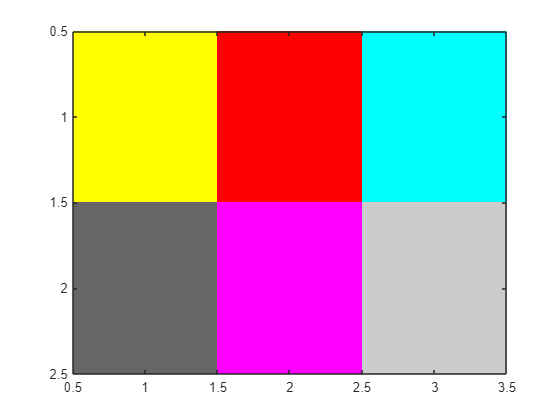

%map för färger
map=([1 1 0; 1 0 0; 0 1 1; ...
          0.4 0.4 0.4; 1 0 1; ...
          0.8 0.8 0.8]);
image([1, 2, 3; 4, 5, 6]);
colormap(map)


m1 = [2 3 4; -1 3 -2];

N = [1 2 3; 4 5 6; 7 8 9; 10 11 12; 13 14 15];

N(1:3:end,1)

ans =      1
    10



N(1:3:end, :)

ans =      1     2     3
    10    11    12


v1 = [1, 1, 1, 1];
v2 = [0.5, 0.25, 0, 0.25];
v3 = [0.25, 0.5, 0, 0.5, 1];
s1 = sum(v1 .* v2)

s1 = 1

%s2 = sum(v1 .* v3) funkar ej lol

a = 5;
b = 4;

l1 = (a ==5)

l1 = logical
   1


l2 = (a >= 4)

l2 = logical
   1


l3 = (a ~= 5)

l3 = logical
   0


l4 = (a ==5 & b==4)

l4 = logical
   1


l5 = (a == 5 | b == 2)

l5 = logical
   1


l6 = ( a > 3 & b < 2)

l6 = logical
   0



m4=[2 3; -1 4];
m5 = [-1 2; 3 8];

l7 = m4 > 3

l7 = 2×2 logical array
   0   0
   0   1


l8 = (m4 >= 3) & (m5 < 8)

l8 = 2×2 logical array
   0   1
   0   0


l9 = m4 > m5

l9 = 2×2 logical array
   1   1
   0   0



m6 = [1 2 3; 4 5 6; 7 8 9];
m7 = [-2 3 1; 0 2 -7; 1 3 6];

u1 = m6 > 3

u1 = 3×3 logical array
   0   0   0
   1   1   1
   1   1   1


u2 = (m6 > 3 & m7 == -7)

u2 = 3×3 logical array
   0   0   0
   0   0   1
   0   0   0


u3 = (m6 > 3 | m7 == -7)

u3 = 3×3 logical array
   0   0   0
   1   1   1
   1   1   1


u4 = ((m6+m7) >= 4 & m6>5)

u4 = 3×3 logical array
   0   0   0
   0   0   0
   1   1   1


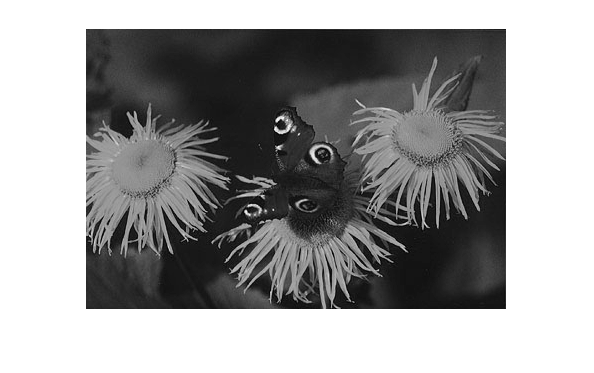

butterflyColor = imread('Butterfly.tif');
mygray = butterflyColor(:,:,1)/3 + butterflyColor(:,:,2)/3 + butterflyColor(:,:,3)/3;
imshow(mygray)

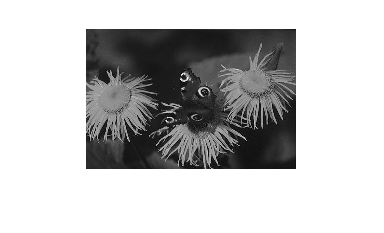

b61 = mygray(1:2:end, 1:2:end);
imshow(b61)

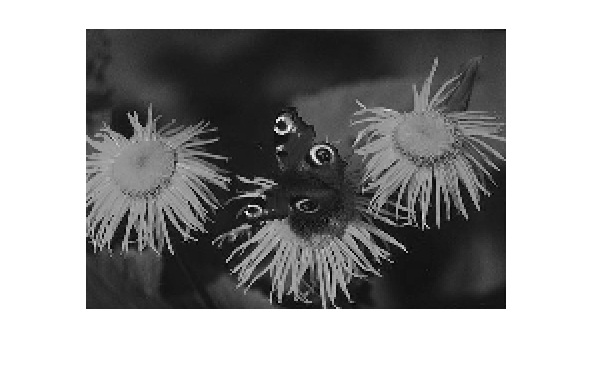

b63_nearest = imresize(b61, 2,"nearest");
b63_linear = imresize(b61, 2, "bilinear");
b63_cubic = imresize(b61, 2, "bicubic");

imshow(b63_nearest)

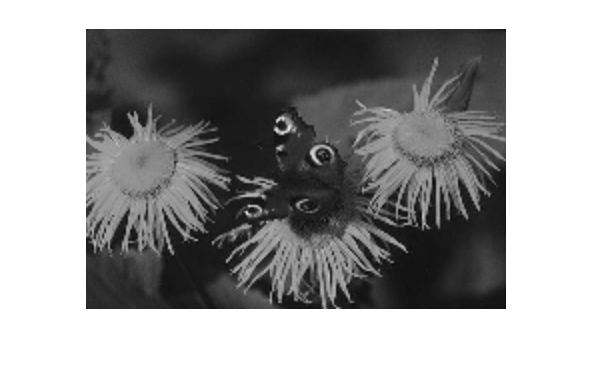

imshow(b63_linear)

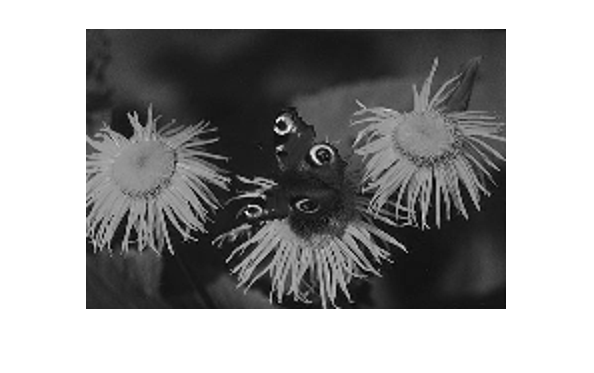

imshow(b63_cubic)

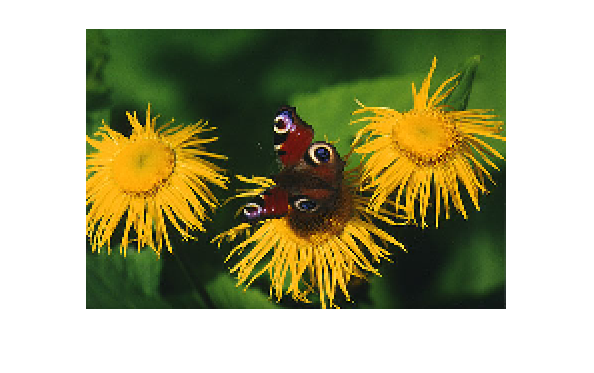

mycolorimage = imread("Butterfly.tif");
mycolorimage = imresize(mycolorimage, 0.5,"nearest");
b64 = imresize(mycolorimage, 2, "nearest");
imshow(b64);

mycolorimage = imread("Butterfly.tif");

G = mycolorimage(:,:,2);
R1 = imresize(mycolorimage(:,:,1), 0.5,'nearest');
B1 = imresize(mycolorimage(:,:,3),0.5,'nearest');
R2 = imresize(R1, 2, 'nearest');
B2 = imresize(B1, 2, 'nearest');
b65 = cat(3,R2, G, B2);

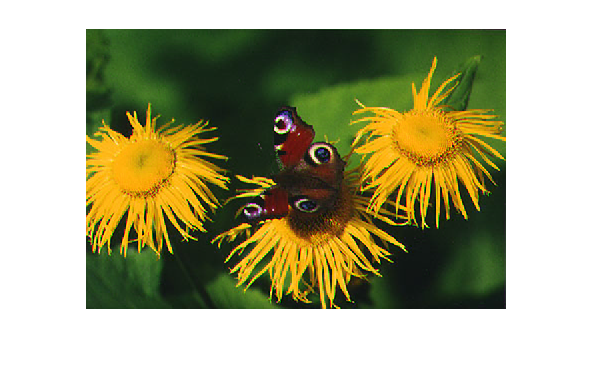

imshow(b65)

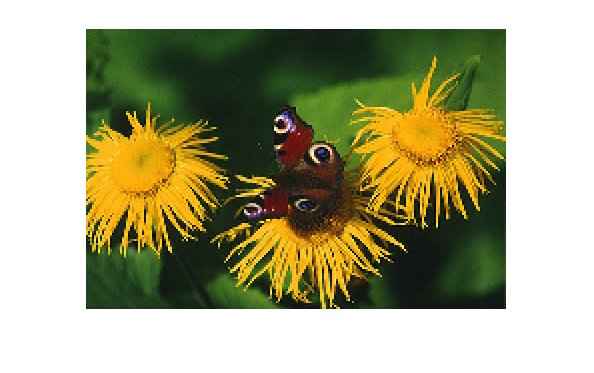

B= mycolorimage(:,:,3);
R1 = imresize(mycolorimage(:,:,1), 0.5,'nearest');
G1 = imresize(mycolorimage(:,:,2),0.5,'nearest');
R3 = imresize(R1, 2, 'nearest');
G3 = imresize(G1, 2, 'nearest');
b67 = cat(3,R3, G3, B);

imshow(b67);

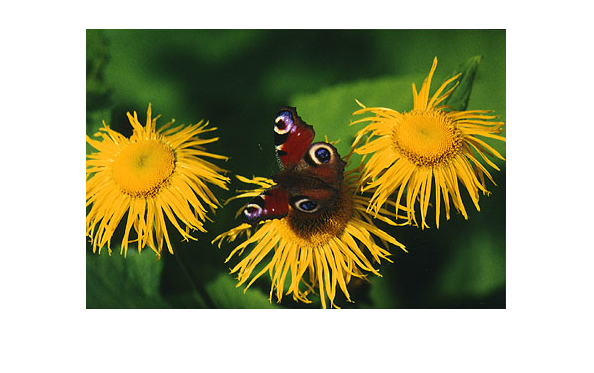

MCI = imread("Butterfly.tif");
MCI = im2double(MCI);

bild1 = MCI(:,:,1) + MCI(:,:,2) + MCI(:,:,3);
bild2= MCI(:,:,1) - MCI(:,:,2);
bild3 = MCI(:,:,1) + MCI(:,:,2) - 2*MCI(:,:,3);

R = bild1/3 + bild2/2 + bild3/6;
G = bild1/3 - bild2/2 + bild3/6;
B = bild1/3 - bild3/3;
b68 = cat(3, R, G, B);

imshow(b68)

imwrite(b68,"b68.png")

B1 = uint8(zeros(4000,12000));
[rad,kolumn] = size(B1(:,:))

rad = 4000

kolumn = 12000

whos B1

  Name         Size                  Bytes  Class    Attributes

  B1        4000x12000            48000000  uint8              



B2 = imresize(B1,0.25,'nearest');
whos B2

  Name         Size                Bytes  Class    Attributes

  B2        1000x3000            3000000  uint8              



B3 = imresize(B1, 0.25, 'bilinear');
whos B3

  Name         Size                Bytes  Class    Attributes

  B3        1000x3000            3000000  uint8              



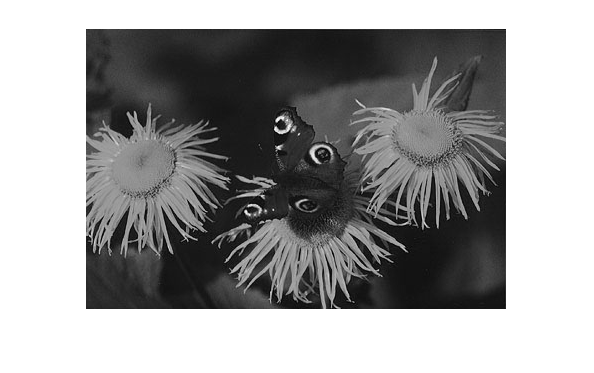

%b62
butterflyColor = imread('Butterfly.tif');
butterflyColor = im2double(butterflyColor);
mygray = butterflyColor(:,:,1)/3 + butterflyColor(:,:,2)/3 + butterflyColor(:,:,3)/3;
imshow(mygray);

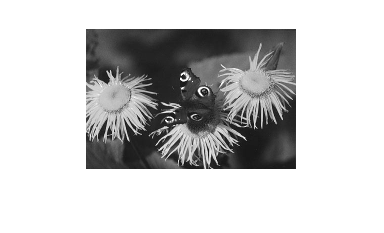

b62 = samplaner(mygray);
imshow(b62)